# Main script

Within this file, everything you need to find and evaluate your magnetic field can be found! Make sure to modify values where it's suggested, and to only run the blocks you need!

## Determine magnetic moment of dipoles

Simulate the magnetic field which arises from a collection of ideal magnetic dipoles, and determine how their magnetization should be set to achieve a target magnetic profile.

### Set general parameters

%% Here, specify where all dipoles are located. These position must me
% explicitly specified. Each row corresponds to a dipole, and its columns
% are x, y and z positions.
dipole_positions = dipole_array([-2 2], [-2 2], [-1 1]);

% Now, for each dipole, specify its magnetic moment. Every row should
% relate to the magnetic moment of the dipole of the same row in
% 'dipole_positions'. Set values to 'nan' to indicate that the values
% should be determined by a target field.
dipole_M = repmat([nan, nan, nan], height(dipole_positions), 1);

% Here, specify on which domain to evaluate the B-field. Currently, only
% discs normal to the z-axis are available
target_domain = graphene([0, 0, 1], 1, pi/4);

% Finally, specify the target magnetic field profile. Any undetermined dipole
% magnetizations will be set to approximate this field, on a 2D-domain
% defined above.
target_field_elementwise = B_field_linear_x(target_domain, 1);

### Set computational parameters

These parameters only affect the computational accuracy, not the problem statement

%% Ö
collision_threshold = 0.01;

### Compute stuff

Now, let the magic happen! 

%% Check if any dipole is situated exactly in the evaluation area 
dipole_in_domain = false;
% Use line below (but fix it plz) if you're really worried about this
% any(dipole_positions(:, 3) == target_domain.Z)

threshold = collision_threshold * dipole_in_domain;

% Create function from degrees-of-freedom to magnetization:
n = sum(isnan(dipole_M), 'all');
get_M = @(x) insert_params(x, dipole_M);

% Create function handle which returns a vector-type field computator from
% params x
B_func_from_x = @(x) B_function(@(xvar, X, Y, Z) get_field(X, Y, Z, dipole_positions, get_M(xvar), threshold), x);

% Create a reference field computator handle
B_0 = B_function(@(~, X, Y, Z) cell2mat(arrayfun(@(x, y, z) reshape(target_field_elementwise(x, y, z), [1 1 3]), X, Y, Z, 'UniformOutput', false)));

% Create an inner product evaluator, with information about evaluation
% domain.
inprod = inner_product(target_domain.R, target_domain.Origin, target_domain.Phi);

% GO!!!
[x, B_best] = granny_smith(B_func_from_x, B_0, inprod, n);

Starting to compute inner product between 1 and 1
It took 0.026005 s
Starting to compute inner product between 2 and 1
It took 0.03443 s
Starting to compute inner product between 2 and 2
It took 0.013717 s
Starting to compute inner product between 3 and 1
It took 0.021652 s
Starting to compute inner product between 3 and 2
It took 0.015363 s
Starting to compute inner product between 3 and 3
It took 0.012603 s
Starting to compute inner product between 4 and 1
It took 0.023722 s
Starting to compute inner product between 4 and 2
It took 0.018985 s
Starting to compute inner product between 4 and 3
It took 0.02287 s
Starting to compute inner product between 4 and 4
It took 0.012091 s
Starting to compute inner product between 5 and 1
It took 0.012246 s
Starting to compute inner product between 5 and 2
It took 0.022026 s
Starting to compute inner product between 5 and 3
It took 0.019714 s
Starting to compute inner product between 5 and 4
It took 0.028454 s
Starting to compute inner product be

### Plotting the result

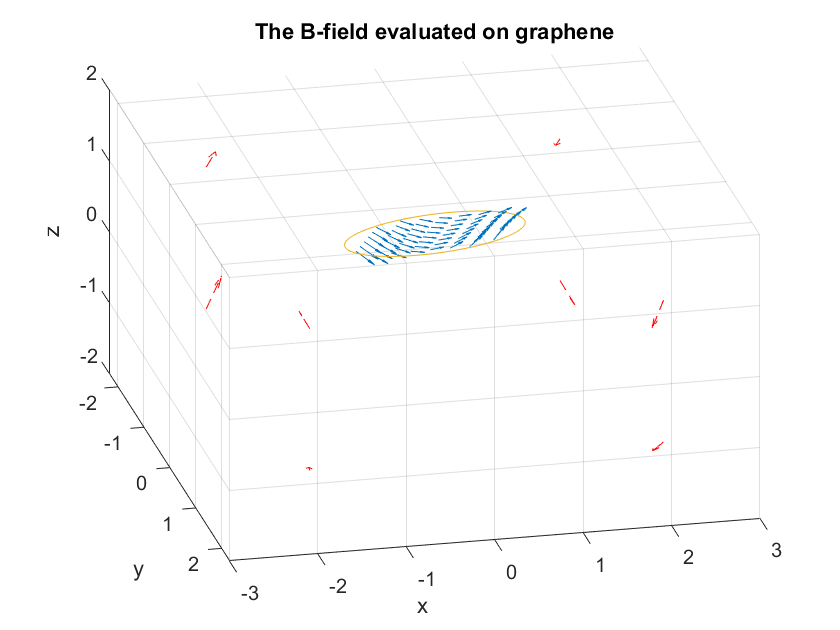

%% Select the amount of discretization points
N = 10;

% Create the mesh
% Create the mesh
[X,Y,Z] = meshgrid(linspace(-target_domain.R,target_domain.R,N),...
    linspace(--target_domain.R,-target_domain.R,N),0);

i = X.^2 + Y.^2 <= 1;

[X, Y, Z] = target_domain.Transform(X, Y, Z);


% Assigns the B-field and shows the quiver plot
B = B_best(X,Y,Z);
Bx = squeeze(B(:,:,1));
By = squeeze(B(:,:,2));
Bz = squeeze(B(:,:,3));

m = get_M(x);

b_plot(X(i),Y(i),Z(i),Bx(i), By(i), Bz(i) ,dipole_positions,m,target_domain)